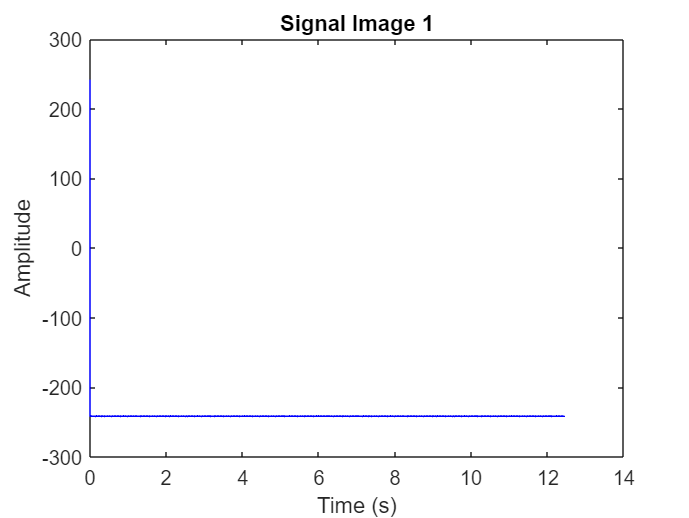

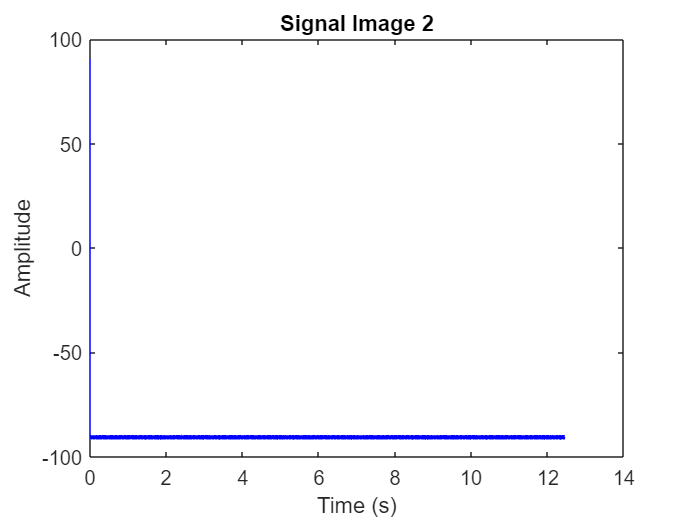

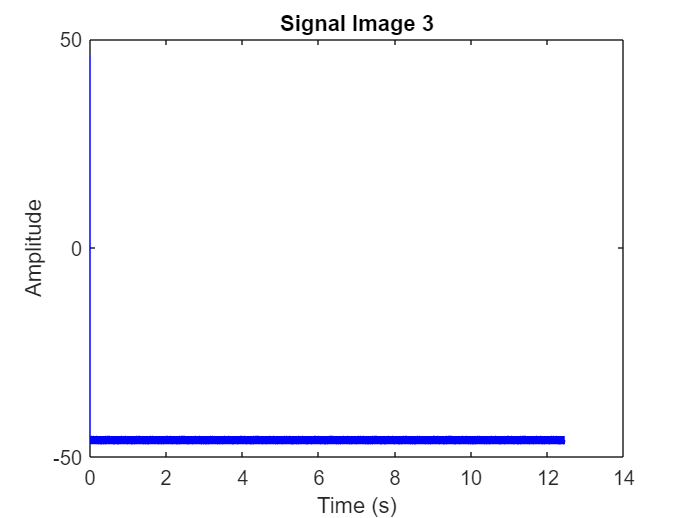

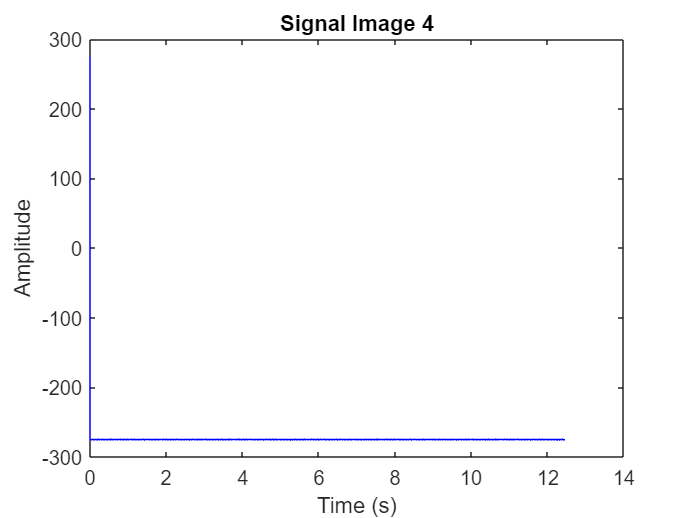

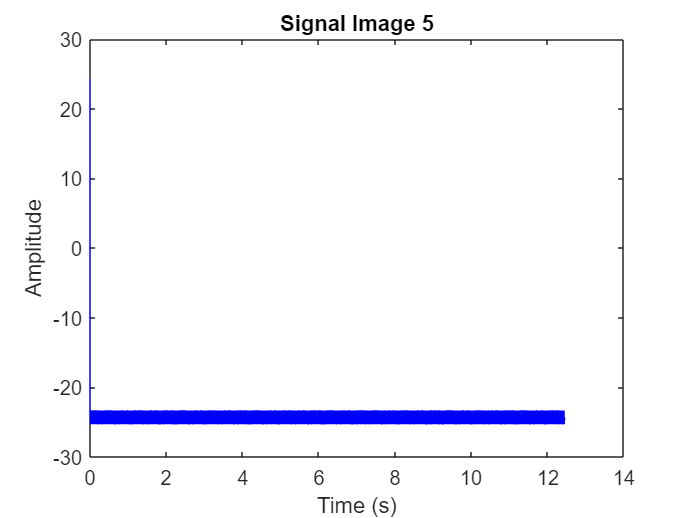

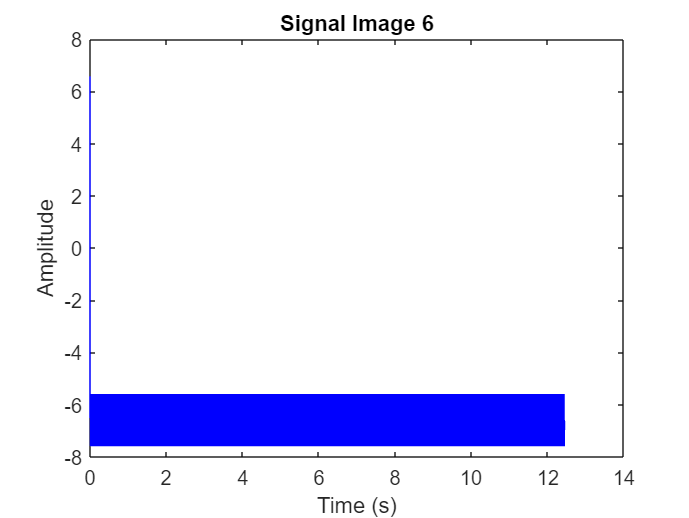

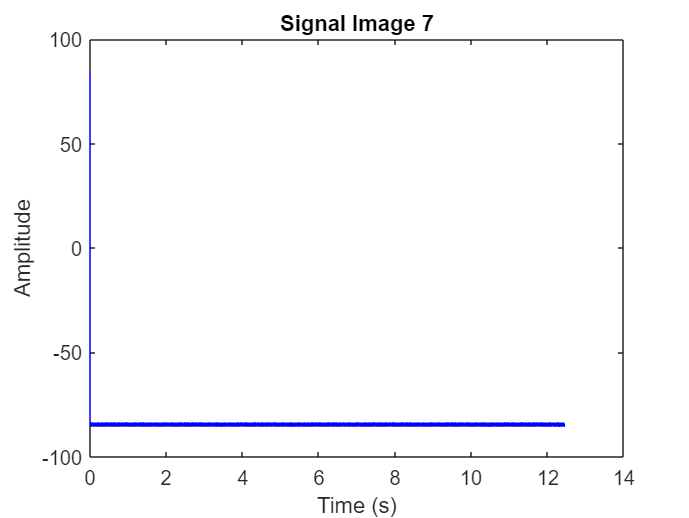

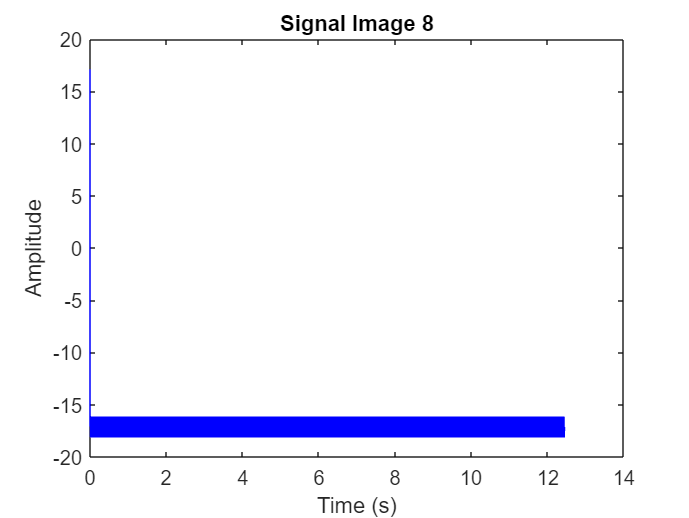

% Parameters
A = 1;                   % Amplitude
f = 50;                  % Frequency in Hz
sampling_rate = 3200;    % Sampling rate in Hz
num_cycles = 622;        % Number of cycles considered

% Time vector
T = 1 / f;                                      % Period of one cycle
duration = num_cycles * T;                      % Total duration of the signal
num_samples = duration * sampling_rate + 1;     % Number of samples
t = linspace(0, duration, num_samples);         % Time vector

% Angular frequency of the sinusoidal signal
omega = 2 * pi * f;
num_signals = 50;
u = @(t) ones(size(t)) .* (t >= 0);

% Generate 50 images of signals
for signal_index = 1:num_signals
    % Define parameters
    tc = rand() * T;          % Randomly select tc between 0 and T
    td = tc + 0.01 + 0.04 * rand();  % Randomly select td between tc + 0.01 and tc + 0.05
    k = 0.1 + 0.3 * rand();   % Randomly select k between 0.1 and 0.4
    N = [1, 2, 4, 6, 8];      % Values of N
    N_index = randi(length(N));  % Randomly select N from the list
    N = N(N_index);
    
    % Calculate the signal
    signal = (sin(omega * t - tc) - sign(omega * t - tc) .* sum(cell2mat(arrayfun(@(n) k * (u(t - (tc + 0.02 * n)) - u(t - (td + 0.02 * n))), 0:(N-1), 'UniformOutput', false)), 2));
    
    % Plot the signal
    figure;
    plot(t, signal, 'b-');
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Signal Image ', num2str(signal_index)]);
end